**Sensors Location**

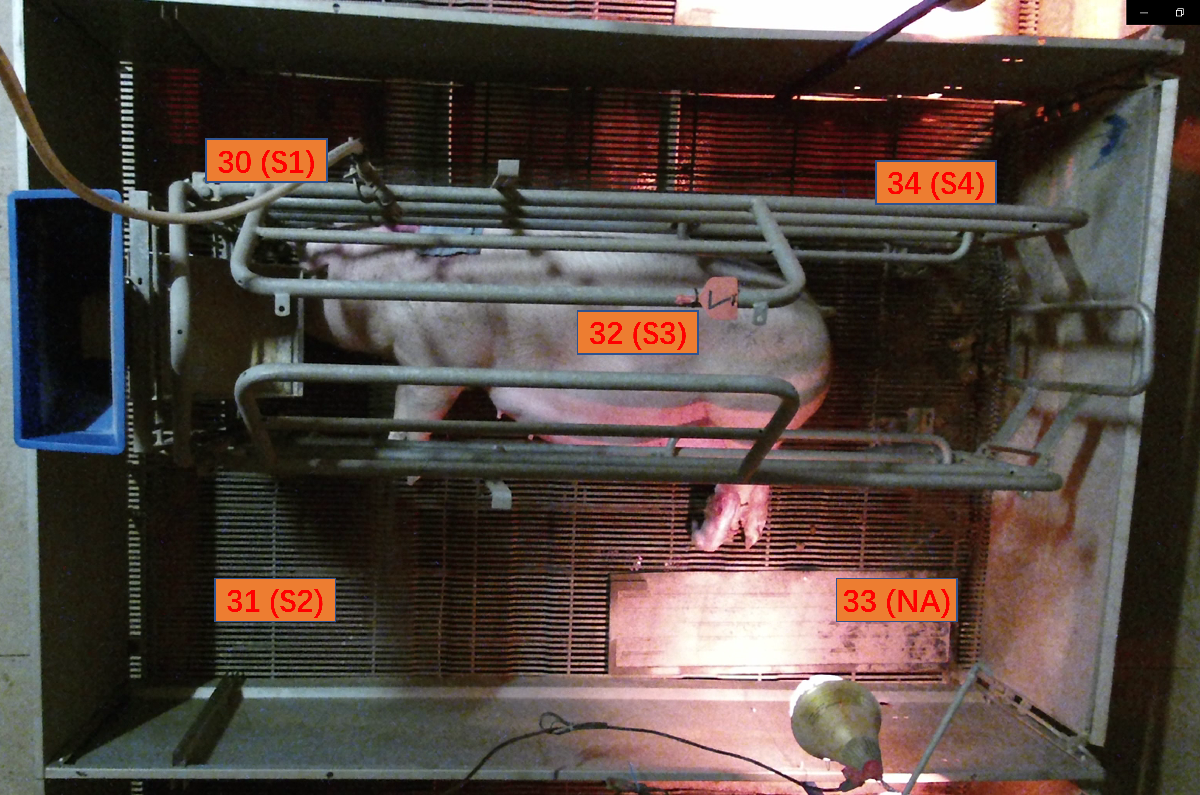

**Extract time from frames (T.mat)**

fig_path = 'all_fig\';
T = [];
for i = 0:length(dir(fig_path))-3
    
    fig_name = [num2str(i),'.jpg'];
    im = imread(strcat(fig_path, fig_name));
    
    im1 = imcrop(im,[0 65 210 50]);
    ocrResults = ocr(im1);
    txt = ocrResults.Text;
    
    year = str2num(txt(1:4));
    month = str2num(txt(6:7));
    day = str2num(txt(9:10));
    
    im2 = imcrop(im,[0 120 170 50]); 
    ocrResults = ocr(im2);
    txt = ocrResults.Text;
    txt = strrep(txt,' ','');
    
    hour = str2num(txt(1:2));
    minute = str2num(txt(4:5));
    second = str2num(txt(7:8));
    
    t = datetime(year,month,day,hour,minute,second,'TimeZone','America/Chicago',...
            'InputFormat','yyyy-MM-dd HH:mm:ss');
    T = [T;t];
end
save('T.mat', 'T');

**Extract Raw Signal Data**

date = '03-06';
fs = 500; 
sensor_list = [30,31,32,33,34]; % 30, 31, 32, (33), 34
hour_list = [3,4, 5,6];
d = load_signal_data(date, fs, sensor_list, hour_list);

sensor:30
sensor:31
sensor:32
sensor:33
sensor:34


**Drop Sensor 33's Data**

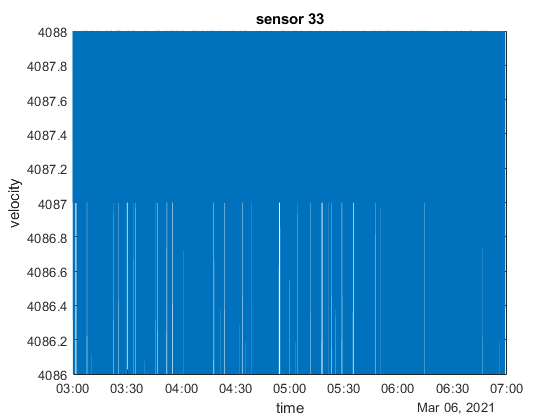

clf
plot(d{4,1}, d{4,2}); 
xlabel('time');
ylabel('velocity');
title("sensor 33");

d(4,:) = [];

**Extract the Corresponding Time Range (**$T_1 \;$**- **$\Delta$** ~ **$T_1$** + **$\Delta$**)**

load T.mat
delta = duration(0,0,10);
disp(["T(1)", string(T(1)),"T(end)", string(T(end))]);

    "T(1)"    "06-Mar-2021 03:29:28"    "T(end)"    "06-Mar-2021 05:59:52"



for i = 1:4
    idx = find(d{i,1}>=T(1)-delta & d{i,1} <= (T(end)+delta));
    d{i,1} = d{i,1}(idx);
    d{i,2} = d{i,2}(idx);
    disp([d{i,1}(1),d{i,1}(end)]);
end

   06-Mar-2021 03:29:18.000000   06-Mar-2021 06:00:02.000000

   06-Mar-2021 03:29:18.000000   06-Mar-2021 06:00:02.000000

   06-Mar-2021 03:29:18.000000   06-Mar-2021 06:00:02.000000

   06-Mar-2021 03:29:18.000000   06-Mar-2021 06:00:02.000000



save('raw_data.mat', "d");

**Plot time domian ~ # nursing**

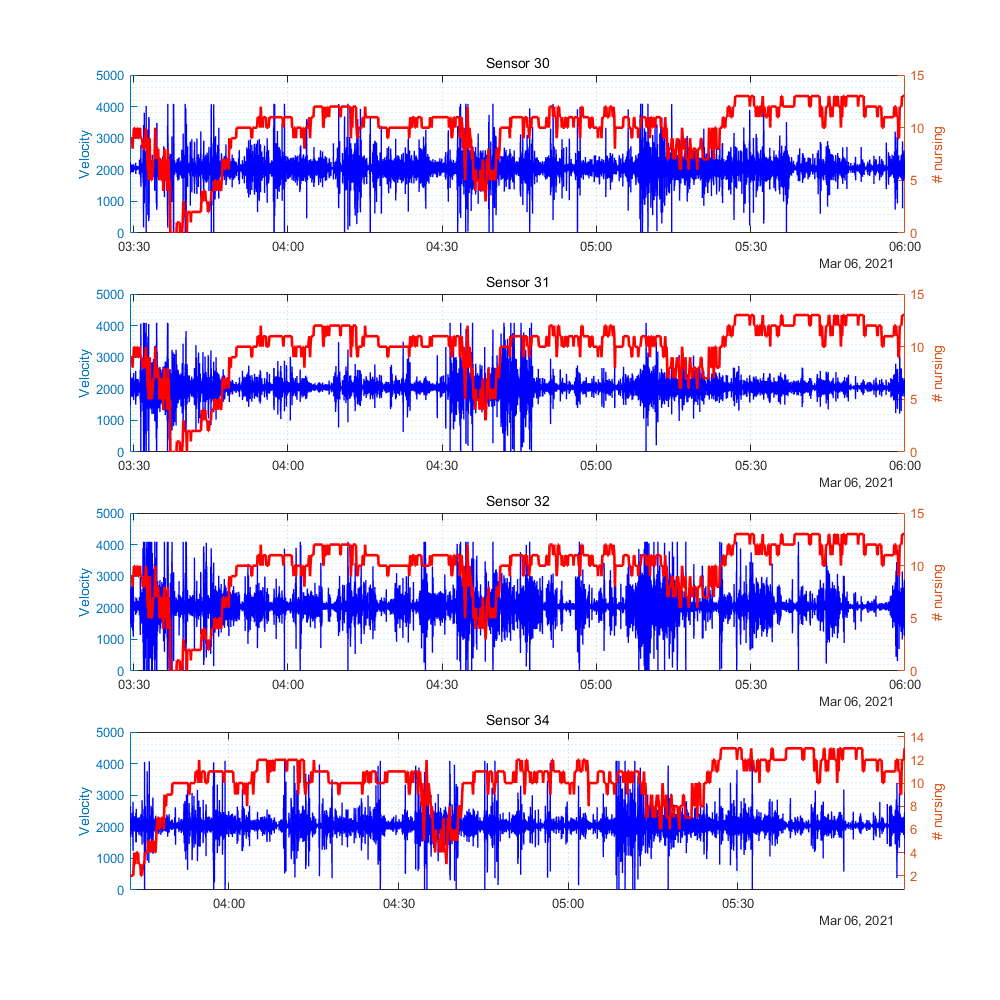

clear;clc
load raw_data.mat
load T.mat
labels_nursing = importdata("labels_nursing.xlsx");
nursing_num = labels_nursing.data(:,3);

sensor_list = [30, 31, 32, 34];
clf
set(gcf,'position',[10,10,1000,1000])

for i = 1:4
    subplot(4,1,i);
    yyaxis left
    p1 = plot(d{i,1}, d{i,2},'-','LineWidth',1);
    xlim([d{i,1}(1),d{i,1}(end)]);
    p1.Color=[0,0,1,0.5];
    ylabel("Velocity");
    hold on;
    yyaxis right
    plot(T, nursing_num, 'r-','LineWidth',2);
    ylabel("# nursing");
    grid minor;
    subtitle(['Sensor ', num2str(sensor_list(i))]);
end

Find the Corresponding Signal Data - ($T_i$ - $\delta$ , $T_i$ + $\delta$ )

sensor data 30


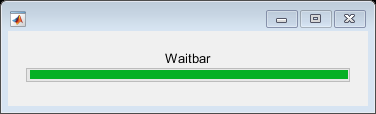

    "3"    "06-Mar-2021 03:29:43"

    "37"    "06-Mar-2021 03:33:00"

    "69"    "06-Mar-2021 03:36:17"

    "89"    "06-Mar-2021 03:38:15"

    "123"    "06-Mar-2021 03:41:32"

    "188"    "06-Mar-2021 03:48:07"

    "213"    "06-Mar-2021 03:50:44"

    "280"    "06-Mar-2021 03:57:18"

    "338"    "06-Mar-2021 04:03:13"

    "350"    "06-Mar-2021 04:04:32"

    "388"    "06-Mar-2021 04:08:28"

    "394"    "06-Mar-2021 04:09:08"

    "437"    "06-Mar-2021 04:13:05"

    "443"    "06-Mar-2021 04:13:43"

    "450"    "06-Mar-2021 04:14:23"

    "464"    "06-Mar-2021 04:15:42"

    "571"    "06-Mar-2021 04:26:13"

    "578"    "06-Mar-2021 04:26:51"

    "629"    "06-Mar-2021 04:32:07"

    "648"    "06-Mar-2021 04:34:06"

    "679"    "06-Mar-2021 04:37:23"

    "857"    "06-Mar-2021 04:55:46"

    "877"    "06-Mar-2021 04:57:44"

    "891"    "06-Mar-2021 04:59:03"

    "974"    "06-Mar-2021 05:07:35"

    "1067"    "06-Mar-2021 05:17:26"

    "1099"    "06-Mar-2021 05:20:43"

    

sensor data 31


    "19"    "06-Mar-2021 03:31:16"

    "99"    "06-Mar-2021 03:39:09"

    "178"    "06-Mar-2021 03:47:02"

    "222"    "06-Mar-2021 03:51:38"

    "269"    "06-Mar-2021 03:56:15"

    "283"    "06-Mar-2021 03:57:34"

    "289"    "06-Mar-2021 03:58:13"

    "301"    "06-Mar-2021 03:59:32"

    "371"    "06-Mar-2021 04:06:45"

    "404"    "06-Mar-2021 04:10:03"

    "440"    "06-Mar-2021 04:13:21"

    "446"    "06-Mar-2021 04:14:00"

    "453"    "06-Mar-2021 04:14:39"

    "474"    "06-Mar-2021 04:16:38"

    "481"    "06-Mar-2021 04:17:17"

    "553"    "06-Mar-2021 04:24:32"

    "567"    "06-Mar-2021 04:25:50"

    "574"    "06-Mar-2021 04:26:30"

    "626"    "06-Mar-2021 04:31:46"

    "658"    "06-Mar-2021 04:35:03"

    "663"    "06-Mar-2021 04:35:43"

    "670"    "06-Mar-2021 04:36:22"

    "724"    "06-Mar-2021 04:41:56"

    "738"    "06-Mar-2021 04:43:16"

    "794"    "06-Mar-2021 04:49:11"

    "857"    "06-Mar-2021 04:55:46"

    "919"    "06-Mar-2021 05:01:42"

   

sensor data 32


    "9"    "06-Mar-2021 03:30:14"

    "93"    "06-Mar-2021 03:38:36"

    "120"    "06-Mar-2021 03:41:13"

    "127"    "06-Mar-2021 03:41:53"

    "134"    "06-Mar-2021 03:42:32"

    "179"    "06-Mar-2021 03:47:08"

    "235"    "06-Mar-2021 03:53:03"

    "255"    "06-Mar-2021 03:55:01"

    "290"    "06-Mar-2021 03:58:17"

    "322"    "06-Mar-2021 04:01:35"

    "335"    "06-Mar-2021 04:02:54"

    "359"    "06-Mar-2021 04:05:32"

    "454"    "06-Mar-2021 04:14:44"

    "468"    "06-Mar-2021 04:16:02"

    "506"    "06-Mar-2021 04:19:59"

    "526"    "06-Mar-2021 04:21:57"

    "589"    "06-Mar-2021 04:27:52"

    "632"    "06-Mar-2021 04:32:28"

    "638"    "06-Mar-2021 04:33:07"

    "683"    "06-Mar-2021 04:37:43"

    "696"    "06-Mar-2021 04:39:02"

    "709"    "06-Mar-2021 04:40:21"

    "741"    "06-Mar-2021 04:43:38"

    "748"    "06-Mar-2021 04:44:17"

    "760"    "06-Mar-2021 04:45:36"

    "774"    "06-Mar-2021 04:46:55"

    "779"    "06-Mar-2021 04:47:34"

    

sensor data 34


    "40"    "06-Mar-2021 03:33:18"

    "86"    "06-Mar-2021 03:37:54"

    "159"    "06-Mar-2021 03:45:08"

    "191"    "06-Mar-2021 03:48:25"

    "197"    "06-Mar-2021 03:49:05"

    "229"    "06-Mar-2021 03:52:22"

    "276"    "06-Mar-2021 03:56:56"

    "365"    "06-Mar-2021 04:06:10"

    "405"    "06-Mar-2021 04:10:07"

    "419"    "06-Mar-2021 04:11:26"

    "454"    "06-Mar-2021 04:14:44"

    "506"    "06-Mar-2021 04:19:59"

    "645"    "06-Mar-2021 04:33:48"

    "786"    "06-Mar-2021 04:48:16"

    "861"    "06-Mar-2021 04:56:09"

    "978"    "06-Mar-2021 05:07:59"

    "1052"    "06-Mar-2021 05:15:52"

    "1071"    "06-Mar-2021 05:17:51"

    "1083"    "06-Mar-2021 05:19:10"

    "1122"    "06-Mar-2021 05:23:06"

    "1142"    "06-Mar-2021 05:25:05"

    "1222"    "06-Mar-2021 05:33:38"

    "1281"    "06-Mar-2021 05:39:33"

    "1287"    "06-Mar-2021 05:40:12"

    "1369"    "06-Mar-2021 05:48:45"

    "1375"    "06-Mar-2021 05:49:24"



clear; clc;
load raw_data.mat
load T.mat

data_X = {};
len = 1250;
sensor_list = [30, 31, 32, 34];
mean_std = [];
for i = 1:4
    disp(['sensor data ',num2str(sensor_list(i))]);
    time_list = d{i, 1};
    data_list = d{i, 2};
    
    % Normalize the data
    mean_i = mean(data_list);
    std_i = std(data_list);
    data_list = (data_list - mean_i) ./ std_i;
    mean_std = [mean_std; [mean_i, std_i]];
    
    time_list_alt = dateshift(time_list, 'start', 'second');
    ts = []; ds = [];
    for j = 1:length(T)
        waitbar(j/length(T));
        idx = find(time_list == T(j));
        if isempty(idx)
%             disp([num2str(j), string(T(j))]);
            idx = find(time_list_alt == T(j),1,'first');
        end
        ti = time_list(idx-len+1:idx+len);
        di = data_list(idx-len+1:idx+len);
        ts = [ts;ti'];
        ds = [ds;di'];
    end
    data_X{i, 1} = ts';
    data_X{i, 2} = ds';
end

save("data_X_+-.mat","data_X", "mean_std");


**Find continous signal data for all sensors**

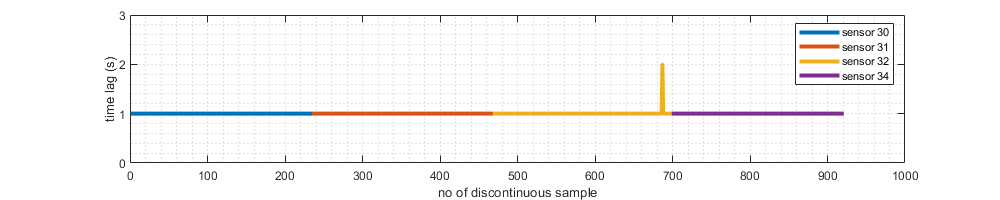

clear; clc
load data_X_+-.mat
load T.mat

standard = time2num(duration('00:04.998000', 'Format', 'mm:ss.SSSSSS'));
continue_idx = {};
uncontinue1 = {};
uncontinue2 = {};

for i = 1:4
    delta = time2num(data_X{i, 1}(end,:) - data_X{i, 1}(1,:)) - standard;
    uncontinue1{i} = delta(delta > 0);
    uncontinue2{i} = delta(delta < 0);
    continue_idx{i} = find(delta == 0);
end

clf;
set(gcf,'position',[10,10,1000,200])
uncontinue1_plot = [1:length(cell2mat(uncontinue1)); cell2mat(uncontinue1)];

idx = [1 cumsum([length(uncontinue1{1}),length(uncontinue1{2}),length(uncontinue1{3}),length(uncontinue1{4})])];
for i = 1:4
    x = uncontinue1_plot(1, idx(i):idx(i+1));
    y = uncontinue1_plot(2, idx(i):idx(i+1));
    plot(x,y, 'LineWidth',3);
    hold on
end
ylabel('time lag (s)');
xlabel("no of discontinuous sample")
legend("sensor 30","sensor 31","sensor 32","sensor 34");
grid minor;
ylim([0,3]);

max(uncontinue1_plot(2,:))

ans = 2

all_continue = intersect(intersect(intersect(continue_idx{1},continue_idx{2},'stable'),...
    continue_idx{3},'stable'), continue_idx{4},'stable');
save('continue_idx.mat', "all_continue");

Plot time domain

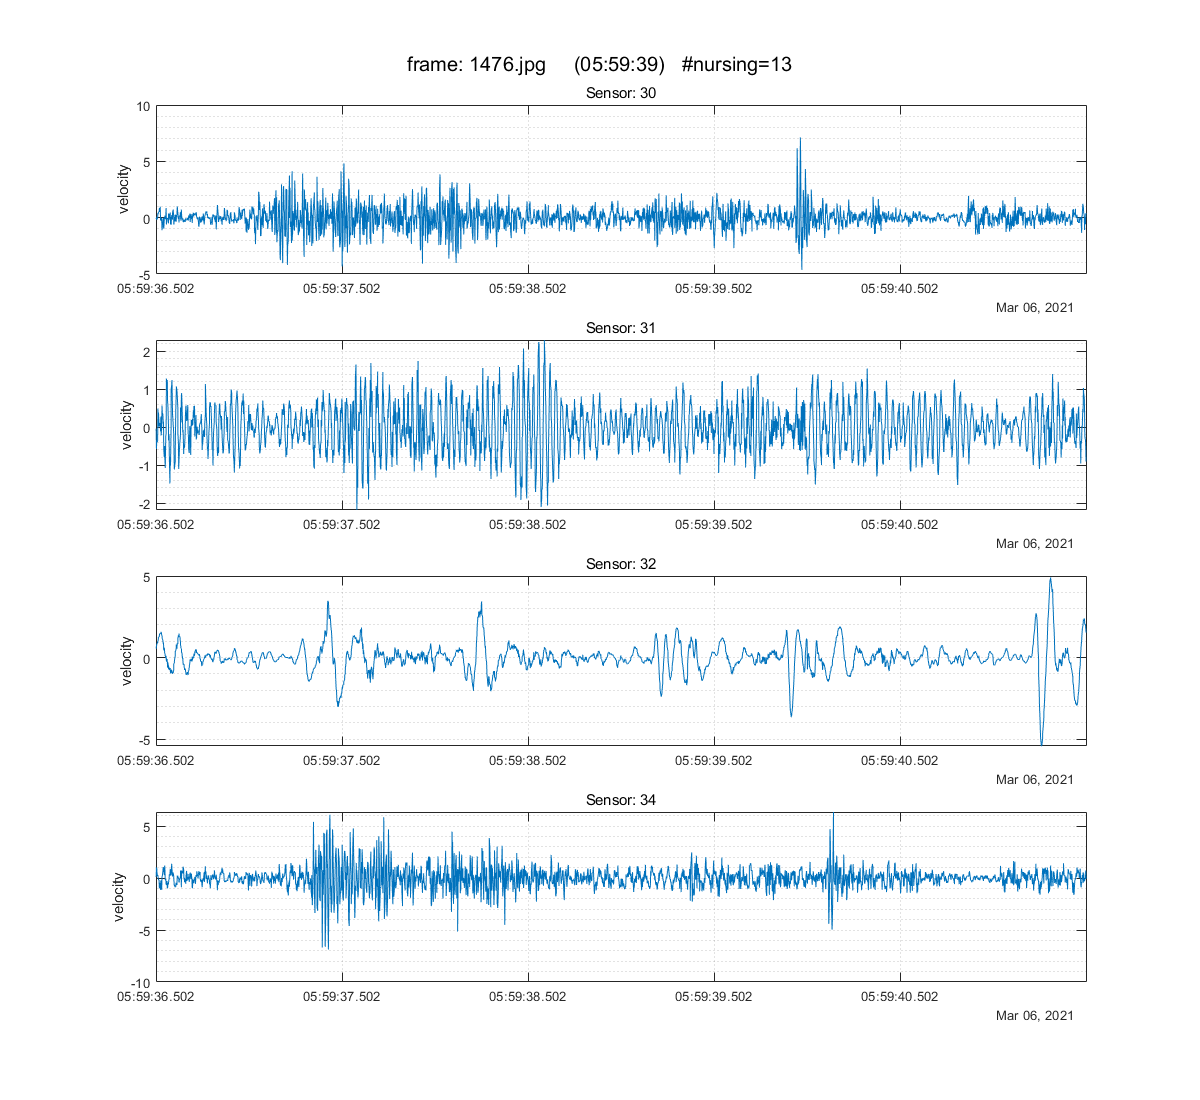

% clear; clc
load data_X_+-.mat
load T.mat
labels_nursing = importdata("labels_nursing.xlsx");
frame_no = labels_nursing.data(:,1);
nursing_num = labels_nursing.data(:,3);

% for i = 0:13
%     mkdir(['time domain plot/nursing ', num2str(i)]);
% end
path = 'time domain plot/';
sensor_list = [30, 31, 32, 34];
issue_list = [];

for i=all_continue
    waitbar(i/length(all_continue));
    clf
    set(gcf,'position',[10,10,1200,1100])
    for j = 1:4
        subplot(4,1,j);
        ti = data_X{j,1}(:,i);
        if  i == 1420 & j == 3
            % 1420th sample time rante error
            ti = data_X{j-1,1}(:,i);
        end
        plot(ti, data_X{j,2}(:,i));
        xticks(ti(1:500:end));
        ylabel("velocity");
        grid minor;
        subtitle(['Sensor: ', num2str(sensor_list(j))]);
    end
    time = char(T(i));
    sgtitle(['frame: ',num2str(frame_no(i)), '.jpg     ', '(', time(end-7:end), ')   #nursing=',num2str(nursing_num(i))])
    saveas(gcf, [path, 'nursing ', num2str(nursing_num(i)), '/', num2str(i), '.jpg']);
end

**Frequency domain**

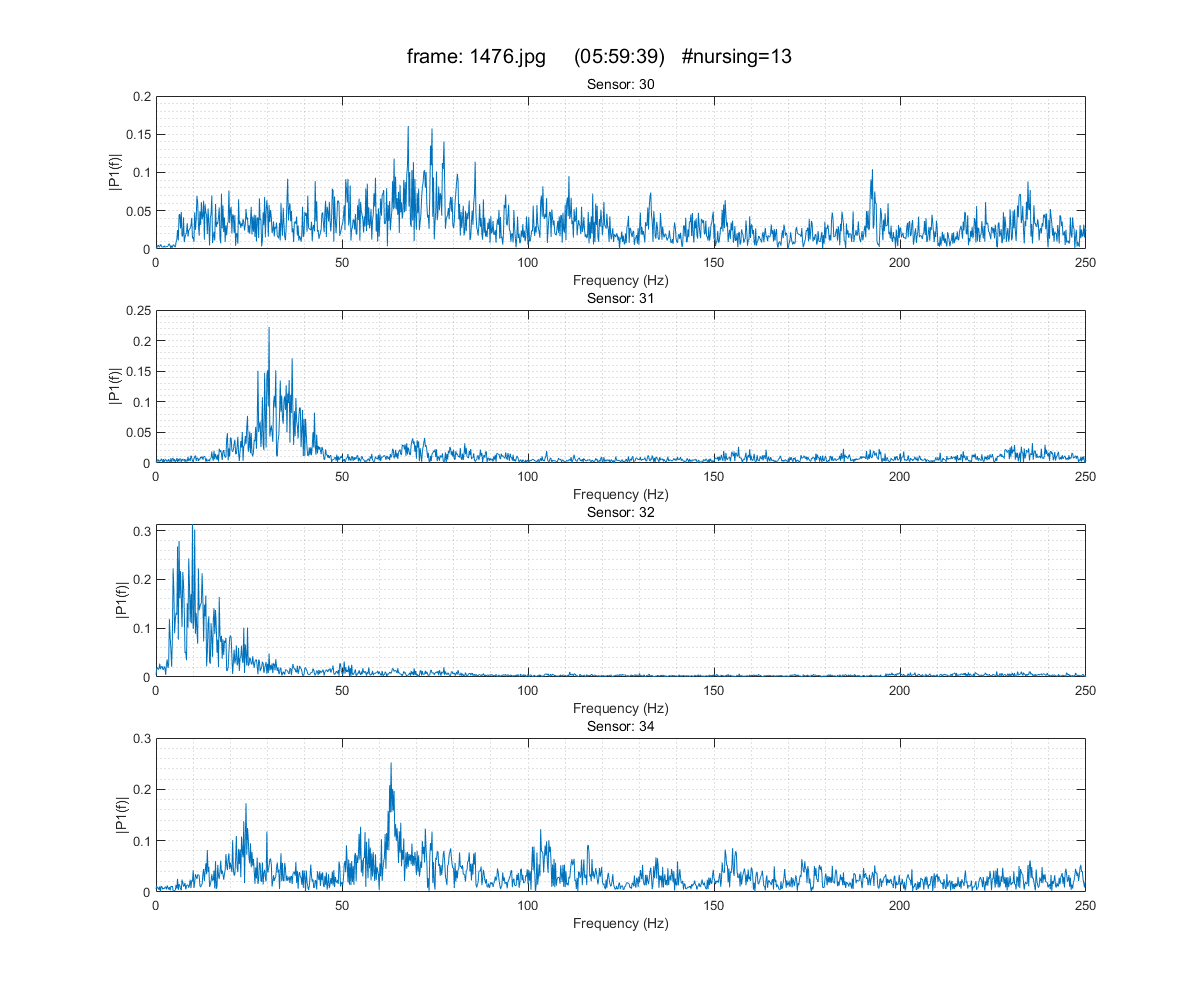

freq_table = 789×98 table
                            frame_no    S30_f10_mean    S30_f30_mean    S30_f50_mean    S30_f70_mean    S30_f90_mean    S30_f110_mean    S30_f130_mean    S30_f150_mean    S30_f170_mean    S30_f190_mean    S30_f210_mean    S30_f230_mean    S31_f10_mean    S31_f30_mean    S31_f50_mean    S31_f70_mean    S31_f90_mean    S31_f110_mean    S31_f130_mean    S31_f150_mean    S31_f170_mean    S31_f190_mean    S31_f210_mean    S31_f230_mean    S32_f10_mean    S32_f30_mean    S32_f50_mean    S32_

clear; clc
load data_X_+-.mat
load continue_idx.mat
load T.mat
labels_nursing = importdata("labels_nursing.xlsx");
frame_no = labels_nursing.data(:,1);
nursing_num = labels_nursing.data(:,3);

% for i = 0:13
%     mkdir(['freq domain plot/nursing ', num2str(i)]);
% end
path = 'freq domain plot/';
fs = 500;
band_width = 20;
freq_features = [];

for i = all_continue
    waitbar(i/length(all_continue));
    data_section4 = [];
    for j = 1:4
        data_section4 = [data_section4, data_X{j,2}(:,i)];
    end
    
    [f_tall, freq_tall, freq_var_tall, f_mean_name, f_var_name] = get_fft_res(data_section4,fs,band_width);
    freq_features = [freq_features, [reshape(freq_tall', [], 1); reshape(freq_var_tall', [], 1)]];
    time = char(T(i));
    sgtitle(['frame: ',num2str(frame_no(i)), '.jpg     ', '(', time(end-7:end), ')   #nursing=',num2str(nursing_num(i))]);
    saveas(gcf, [path, 'nursing ', num2str(nursing_num(i)), '/', num2str(i), '.jpg']);
end

**time features**

time_features = [];
time_features_names = [];
sensor_list = ["30", "31", "32", "34"];
for i = 1:4
    data_i = data_X{i, 2};
    
    t_mean = mean(data_i);
    t_std = std(data_i);
    t_max = max(data_i);
    t_min = min(data_i);
    time_features = [time_features, [t_mean' t_std' t_max' t_min']];
    time_features_names = [time_features_names [string(['S', char(sensor_list(i)), '_mean']),...
        string(['S', char(sensor_list(i)), '_std']), string(['S', char(sensor_list(i)), '_max']),...
        string(['S', char(sensor_list(i)), '_min'])]];
end
time_features = time_features(all_continue, :);


**To table**

feature_table = table([frame_no(all_continue), string(T(all_continue)), time_features, freq_features', nursing_num(all_continue)]);
feature_table = splitvars(feature_table);
feature_table.Properties.RowNames = string(T(all_continue));
feature_table.Properties.VariableNames = ["frame_no", 'Time', time_features_names, f_mean_name',  f_var_name', "nursing_num"];
writetable(feature_table,'feature_table.xlsx');
feature_table

feature_table = 789×115 table
                            frame_no             Time                S30_mean        S30_std       S30_max        S30_min         S31_mean        S31_std       S31_max      S31_min         S32_mean        S32_std       S32_max        S32_min         S34_mean        S34_std       S34_max        S34_min      S30_f10_mean    S30_f30_mean    S30_f50_mean    S30_f70_mean    S30_f90_mean    S30_f110_mean    S30_f130_mean    S30_f150_mean    S30_f170_mean    S30_f190_mean    S30_f210_mean

function [f_tall, freq_tall, freq_var_tall, f_mean_name, f_var_name] = get_fft_res(data_section4,fs,band_width)
    
    clf;
    sensor_list = ["30", "31", "32", "34"];
    
    L = length(data_section4(:,1));
    f = fs*(0:(L/2))/L;
    n_bin = floor(fs/2/band_width);
    f_tall = zeros(4,n_bin); freq_tall = zeros(4,n_bin); freq_var_tall = zeros(4,n_bin);
    f_mean_name = [];
    f_var_name = [];
    for sensor = 1:4
        data_section = data_section4(:,sensor);
        
        
        Y = fft(data_section);
        P2 = abs(Y/L);
        P1 = P2(1:L/2+1);
        P1(2:end-1) = 2*P1(2:end-1);
        P1 = P1';
        
        for i = 1:n_bin % loop over all freq. bands
            start_f = band_width*(i-1);
            end_f = band_width*(i);
            f_tall(sensor,i) = band_width/2 + (i-1)*band_width;
            idx_range = find(f > start_f & f < end_f);
            freq_tall(sensor,i) = mean(P1(idx_range));
            freq_var_tall(sensor,i) = var(P1(idx_range));
            f_mean_name = [f_mean_name; string(['S', char(sensor_list(sensor)), '_f', num2str(f_tall(sensor,i)), '_mean'])];
            f_var_name = [f_var_name; string(['S', char(sensor_list(sensor)), '_f', num2str(f_tall(sensor,i)), '_var'])];
        end
        
        set(gcf,'position',[10,10,1200,1000]);
        subplot(4,1, sensor);
        plot(f, P1);
        ylabel('|P1(f)|');
        grid minor
        subtitle(['Sensor: ', char(sensor_list(sensor))]);
        xlabel('Frequency (Hz)');
    end
    
end

function [f_tall, freq_tall, freq_var_tall] = get_psd_res(data_section4,fs,band_width)

    for sensor = 1:4
        data_section = data_section4(:,sensor);
        
        L = length(data_section);
        Y = fft(data_section);
        P2 = abs(Y/L);
        P1 = P2(1:L/2+1);
        P1(2:end-1) = 2*P1(2:end-1);
        P1 = P1';
        
        psdx = (1/(fs*L)) * abs(Y(1:L/2+1)).^2;
        psdx(2:end-1) = 2*psdx(2:end-1);
        
        f = fs*(0:(L/2))/L;
        
        n_bin = floor(fs/2/band_width);
        f_tall = zeros(1,n_bin); freq_tall = zeros(1,n_bin); freq_var_tall = zeros(1,n_bin);
    
        for i = 1:n_bin % loop over all freq. bands
            start_f = band_width*(i-1);
            end_f = band_width*(i);
            f_tall(1,i) = band_width/2 + (i-1)*band_width;
            idx_range = find(f > start_f & f < end_f);
            freq_tall(1,i) = mean(P1(idx_range));
            freq_var_tall(1,i) = var(P1(idx_range));
        end
        
        clf;
        set(gcf,'position',[10,10,1200,200])
    %     yyaxis left
        plot(f, P1);
        ylabel('Single-Sided Amplitude Spectrum of X(t)');
    %     yyaxis right
    %     semilogy(f, psdx)
        grid minor
        title('Periodogram Using FFT')
        xlabel('Frequency (Hz)')
    %     ylabel('Power/Frequency (dB/Hz)')
    end

    

end

